# Experiment with Focus Stacking

Experiment with focus stacking using our cp (Computational Photography) classes. Eventually add object and camera motion.

## Create a pbrt scene we can use

Using pbrt lets us get the highest-fidelity rendering. We use its lens model to get realistic depth and occlusion rendering.

ieInit();
setpref('ISET', 'fast_num2string', true); % use faster piWrite
sceneLuminance = 200;
numRays = 64;
filmResolution = 512;

sceneChoice = "Chess Set";
apertureDiameter = 6;% in mm

% for legacy reasons, scenes don't have a uniform naming scheme,
% so we map the user's choice to the appropriate options
if strcmp(sceneChoice, "Cornell Box with Bunny")
    scenePath = 'Cornell_BoxBunnyChart';        
    sceneName = 'cornell box bunny chart';
elseif strcmp(sceneChoice, "CornellBoxReference")
    scenePath = "CornellBoxReference";
    sceneName = "CornellBoxReference";
else
    scenePath = 'ChessSet';
    sceneName = 'chessSet';
end

pbrtCPScene = cpScene('pbrt', 'scenePath', scenePath, 'sceneName', sceneName, ...
    'resolution', [filmResolution filmResolution], ...
    'numRays', numRays, 'sceneLuminance', sceneLuminance, ...
    'lensFile','wide.40deg.6.0mm.json',...
    'apertureDiameter', apertureDiameter); % realistic camera needs .dat

Read 8 materials.
Read 3 textures.
***Scene parsed.



pinholeCPScene = cpScene('pbrt', 'scenePath', scenePath, 'sceneName', sceneName, ...
    'resolution', [filmResolution filmResolution], ...
    'numRays', numRays, ...
    'sceneLuminance', sceneLuminance);

Read 8 materials.
Read 3 textures.
***Scene parsed.


%pinholeCPScene.thisR.set('focaldistance', '.005');

if strcmp(sceneChoice, "CornellBoxReference")
    bunny = load('bunny.mat');
    [~, bunny_id] = pbrtCPScene.thisR.set('asset',1, 'add', bunny.assetTree.Node{1});
    pbrtCPScene.thisR.set('material', 'add', bunny.matList{1});
    
    [~, bunny_id] = pinholeCPScene.thisR.set('asset',1, 'add', bunny.assetTree.Node{1});
    pinholeCPScene.thisR.set('material', 'add', bunny.matList{1});
    
    % in case bunny is out of our frame
    pinholeCPScene.thisR.set('asset', bunny_id, 'translate', [0 .1 0]);
    pbrtCPScene.thisR.set('asset', bunny_id, 'translate', [0 .1 0]);
    %if you want object motion
    %pbrtCPScene.objectMotion = {{bunny_id, [0 .1 0], [0 0 0]}};

    % now calculate the distance of the bunny
    bPos = pbrtCPScene.thisR.recipeGet('asset', bunny_id, 'world position');
    cPos = pbrtCPScene.thisR.lookAt.from;
    
    bDistance = sum((bPos-cPos).^2)^.5;
    
    mcc = load('mccCB.mat');
    [~, mcc_id] = pbrtCPScene.thisR.set('asset',1, 'add', mcc.assetTree.Node{1});
    pbrtCPScene.thisR.set('material', 'add', mcc.matList{1});
    %pbrtCPScene.thisR.set('asset', mcc_id, 'world position', [0, 1, 1]);
    
    bar = load('slantedbar.mat');
    [~, bar_id] = pbrtCPScene.thisR.set('asset',1, 'add', bar.assetTree.Node{1});
    pbrtCPScene.thisR.set('material', 'add', bar.matList{1});

    coord = load('coordinate.mat');
    pbrtCPScene.thisR.set('asset',1, 'add', coord.assetTree.Node{1});
    pbrtCPScene.thisR.set('material', 'add', coord.matList{1});
else
    bDistance = 1;
end

## Create our sample camera

Just one module with a pre-made sensor and default optics.

% some timing code, just to see how fast we run...
setpref('ISET', 'benchmarkstart', cputime); 
setpref('ISET', 'tStart', tic);

% We'll use a pre-defined sensor for our Camera Module, and let it use
% default optics for now. We can then assign the module to our camera:
ourSensor = sensorCreate('imx363'); 
ourSensor = sensorSet(ourSensor, 'size', [512, 1024]);
pinholeSensor = sensorCreate('imx363'); 
pinholeSensor = sensorSet(pinholeSensor, 'size', [512, 1024]);

% cpBurstCamera is a sub-class of cpCamera that implements simple HDR and Burst
% capture and processing
ourCamera = cpBurstCamera(); 
% Cameras can eventually have more than one module (lens + sensor)
% but for now, we just create one using our sensor
ourCamera.cmodules(1) = cpCModule('sensor', ourSensor); 

% try to make the pinhole a pinhole:)
% if it works, should integrate into cpCamera
pinholeCamera = cpBurstCamera();
pinholeCamera.cmodules(1) = cpCModule('sensor', pinholeSensor);
pinholeCamera.cmodules(1).oi.optics = opticsSet(pinholeCamera.cmodules(1).oi.optics,'fnumber',64);

## Let's Look at the Camera we've Created

cpCameraWindow is actually a mini-application, that lets you see the properties of your camera, and the scene you've chosen. You can use it to take photos in whatever modes your camera supports. It also allows to to set Advanced Processing, which tells cameras that support it to do additional processing like image registration and tonemapping, as needed, in their ISP, instead of the default combination of frames in the sensor.

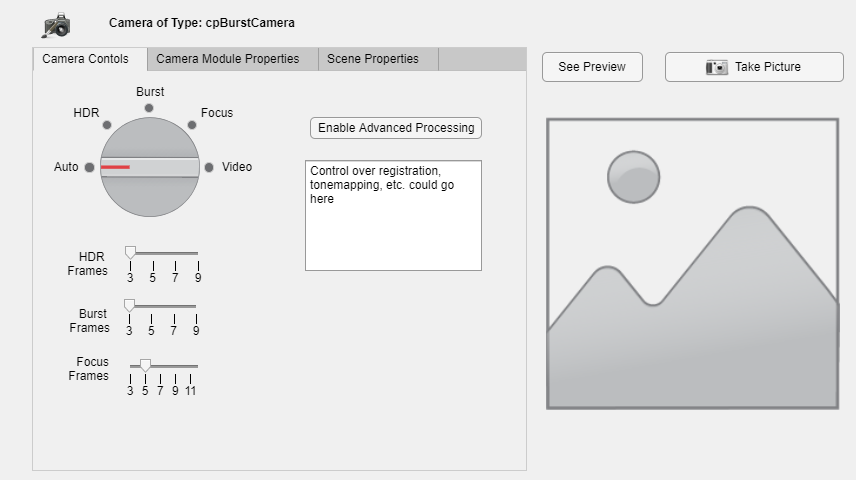

cpCameraWindow(ourCamera, pbrtCPScene);

## Take Pictures

burstImage = ourCamera.TakePicture(pbrtCPScene, 'Burst',...
    'numBurstFrames', 3, 'imageName','Burst',...
    'focusMode', 'Manual', 'focusParam', bDistance* 1.1, 'insensorIP',false);

Overwriting PBRT file B:\iset\iset3d-v4\local\ChessSet\ChessSet.pbrt
Overwriting PBRT file B:\iset\iset3d-v4\local\ChessSet\ChessSet.pbrt
Elapsed time is 0.840731 seconds.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   2.03
Render: docker --context render-vista exec -i  pbrt-gpu-Windows1163 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Rendered remotely in:   6.45
Success!
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   1.50
Complete render took: 1.00e+01 seconds.*** Rendering time for ChessSet:  10.0 sec ***

exr2bin done.exr2bin done.

 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   0.94
Render: docker --context render-vista exec -i  pbrt-gpu-Windows1163 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Rendered remotely in:   6.43
Success!
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   0.74
Complete render took: 8.19e+00 seconds.*** Rendering time for ChessSet:  8.2 sec ***

exr2bin done.exr2bin done.

Overwriting PBRT file B:\iset\iset3d-v4\local\ChessSet\ChessSet.pbrt
Overwriting PBRT file B:\iset\iset3d-v4\local\ChessSet\ChessSet.pbrt
Elapsed time is 0.808349 seconds.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   0.96
Render: docker --context render-vista exec -i  pbrt-gpu-Windows1163 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Rendered remotely in:   8.25
Success!
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   1.38
Complete render took: 1.07e+01 seconds.*** Rendering time for ChessSet:  10.7 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.Overwriting PBRT file B:\iset\iset3d-v4\local\ChessSet\ChessSet.pbrt
Elapsed time is 0.8011

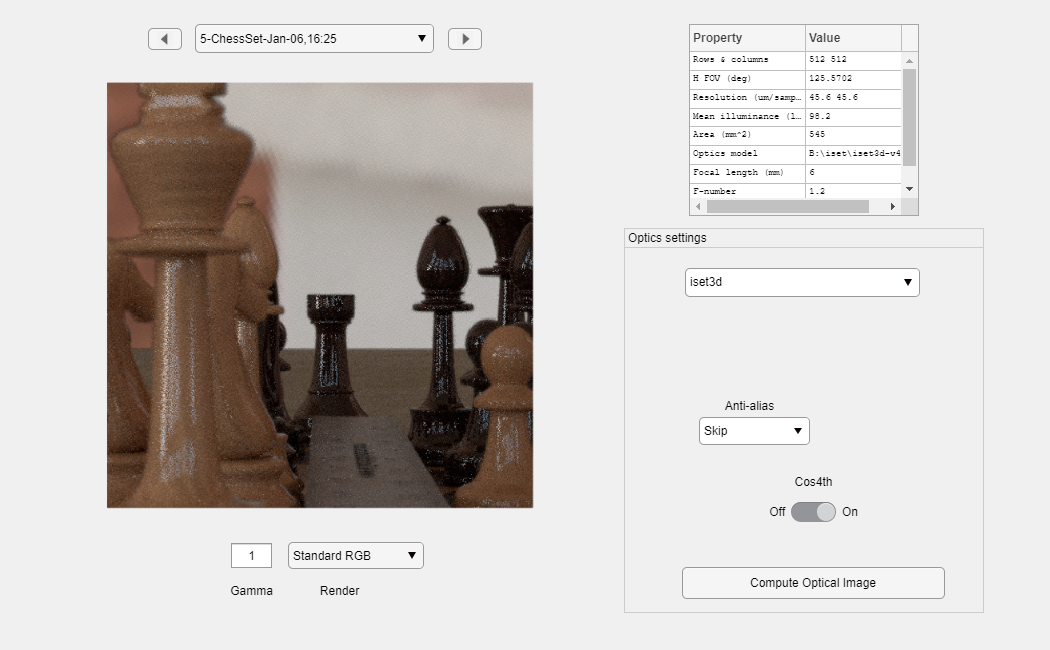

Overwriting PBRT file B:\iset\iset3d-v4\local\ChessSet\ChessSet.pbrt
Overwriting PBRT file B:\iset\iset3d-v4\local\ChessSet\ChessSet.pbrt
Elapsed time is 0.816242 seconds.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.06
Render: docker --context render-vista exec -i  pbrt-gpu-Windows1163 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Rendered remotely in:   6.34
Success!
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   1.06
Complete render took: 8.54e+00 seconds.*** Rendering time for ChessSet:  8.5 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   0.95
Render: docker --context render-vista exec -i  pbrt-gpu-Windows1163 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Rendered remotely in:   6.53
Success!
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   0.74
Complete render took: 8.29e+00 seconds.*** Rendering time for ChessSet:  8.3 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.Overwriting PBRT file B:\iset\iset3d-v4\local\ChessSet\ChessSet.pbrt
Overwriting PBRT file B:\iset\iset3d-v4\local\ChessSet\ChessSet.pbrt
Elapsed time is 0.774331 seconds.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.


stackedImage = ourCamera.TakePicture(pbrtCPScene, 'FocusStack', ...
    'focusMode', 'Stack', 'focusParam', 9, ...
    'imageName','Focus Stacked',...
    'insensorIP',false);

Overwriting PBRT file B:\iset\iset3d-v4\local\ChessSet\ChessSet.pbrt
Overwriting PBRT file B:\iset\iset3d-v4\local\ChessSet\ChessSet.pbrt
Elapsed time is 0.796102 seconds.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.06
Render: docker --context render-vista exec -i  pbrt-gpu-Windows1163 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Rendered remotely in:   6.45
Success!
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   1.49
Complete render took: 9.08e+00 seconds.*** Rendering time for ChessSet:  9.1 sec ***

exr2bin done.exr2bin done.

 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.06
Render: docker --context render-vista exec -i  pbrt-gpu-Windows1163 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Rendered remotely in:   6.47
Success!
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   0.80
Complete render took: 8.41e+00 seconds.*** Rendering time for ChessSet:  8.4 sec ***

exr2bin done.exr2bin done.

Overwriting PBRT file B:\iset\iset3d-v4\local\ChessSet\ChessSet.pbrt
Overwriting PBRT file B:\iset\iset3d-v4\local\ChessSet\ChessSet.pbrt
Elapsed time is 0.792230 seconds.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.06
Render: docker --context render-vista exec -i  pbrt-gpu-Windows1163 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Rendered remotely in:   6.44
Success!
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   1.49
Complete render took: 9.07e+00 seconds.*** Rendering time for ChessSet:  9.1 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

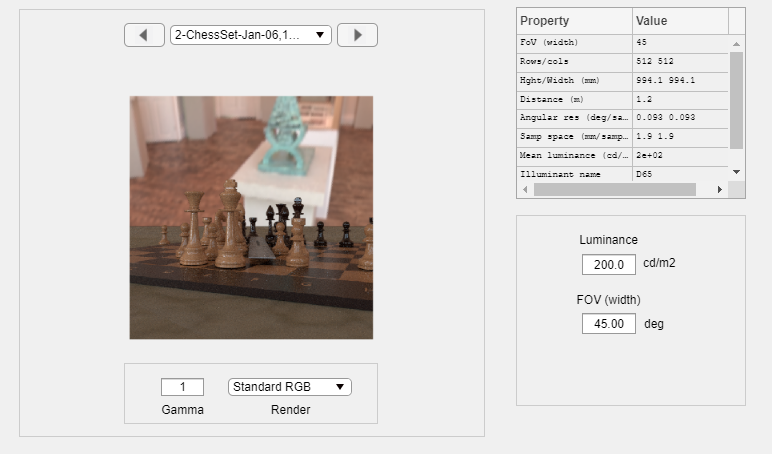


pinholeImage = pinholeCamera.TakePicture(pinholeCPScene, 'Auto',...
    'insensorIP', false);

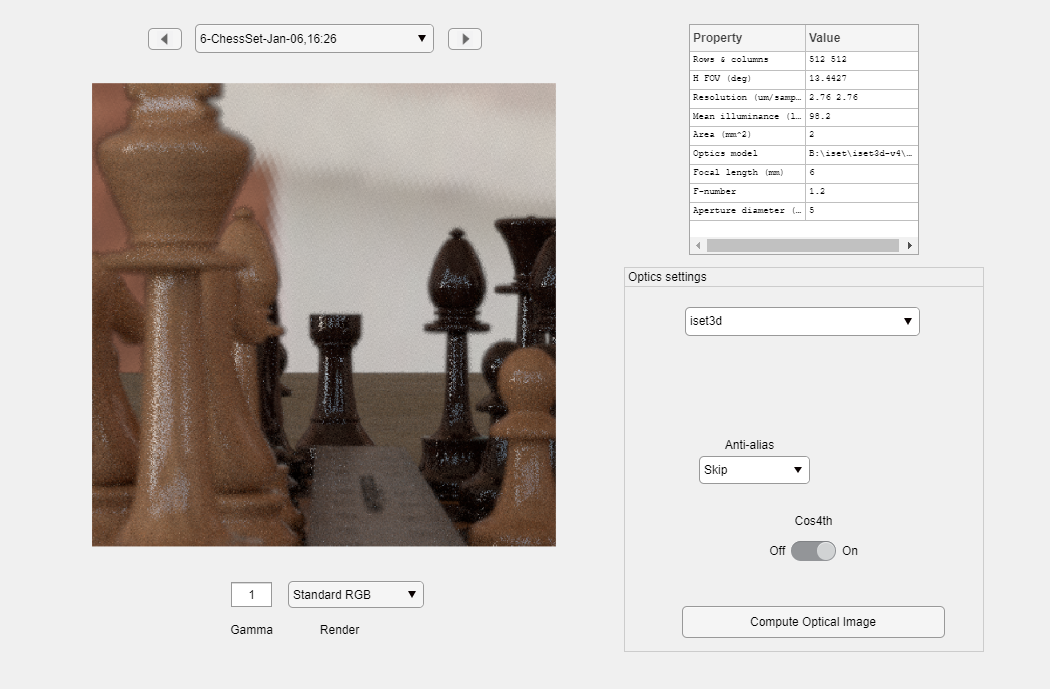

Burst vs. Stacked with no motion

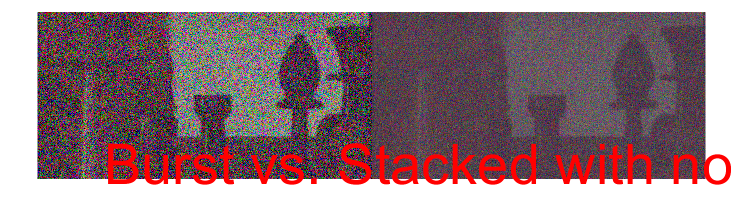


cpCompareImages(burstImage, stackedImage, 'Burst vs. Stacked with no motion');

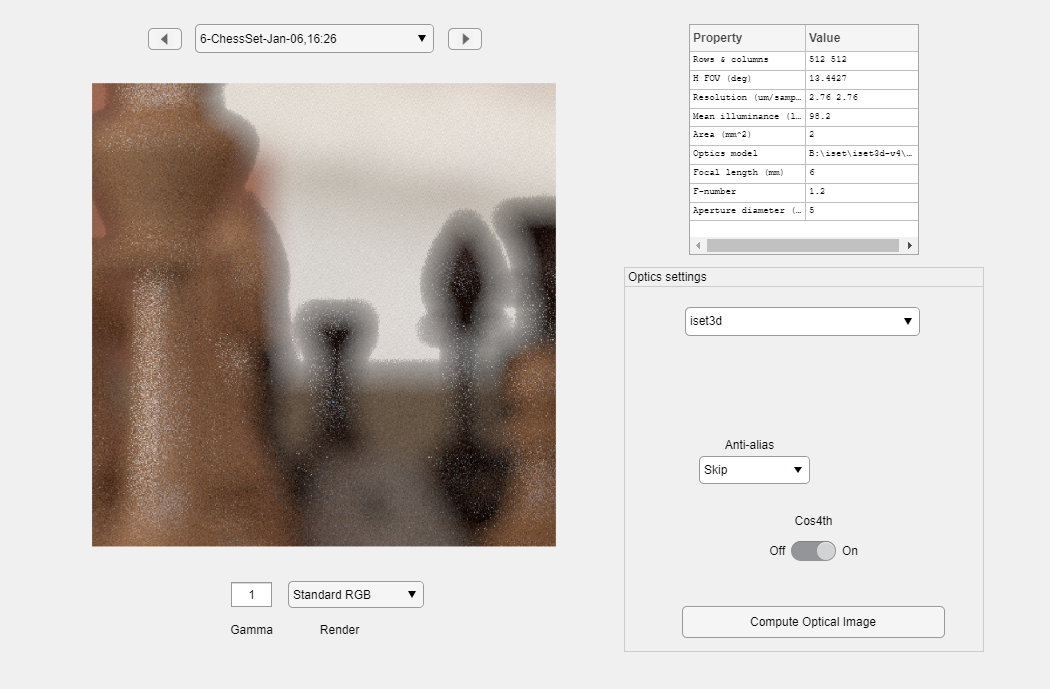

Pinhole vs. Stacked with no motion

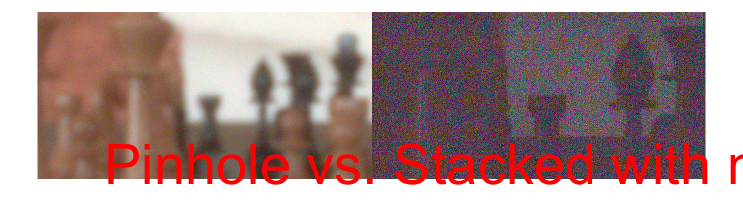

cpCompareImages(pinholeImage, stackedImage, 'Pinhole vs. Stacked with no motion');

Pinhole vs. Burst with no motion

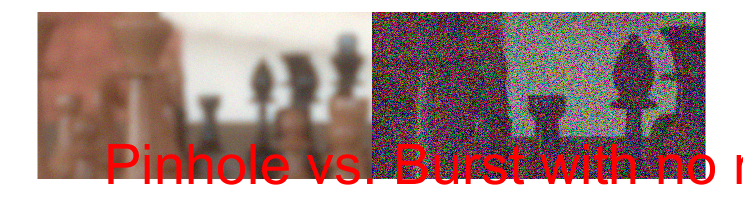

cpCompareImages(pinholeImage, burstImage, 'Pinhole vs. Burst with no motion');

## Print out some timing stats

Just for human consumption

tTotal = toc(getpref('ISET','tStart'));
afterTime = cputime;
beforeTime = getpref('ISET', 'benchmarkstart', 0);
glData = opengl('data');
disp(strcat("cpCompare ran  on: ", glData.Vendor, " ", glData.Renderer, "with driver version: ", glData.Version)); 

cpCompare ran  on: NVIDIA Corporation NVIDIA GeForce RTX 3090/PCIe/SSE2with driver version: 4.6.0 NVIDIA 510.06


disp(strcat("cpCompare ran  in: ", string(afterTime - beforeTime), " seconds of CPU time."));

cpCompare ran  in: 192.1719 seconds of CPU time.


disp(strcat("cpCompare ran  in: ", string(tTotal), " total seconds."));

cpCompare ran  in: 484.4991 total seconds.
